# Testing the Top- and Bottom Hat transformation

In this script we test the top- and bottom transformation from the **TopBotHat.mlx** script.

From this script we concluded that we can use the bottom hat transformation to intensify the black holes to white ones, with a disk as structuring element with radius 100.

When using these results to detect the circles in the image and comparing them to the original way we detected the circles, we conclude that this wasn't really usefull.

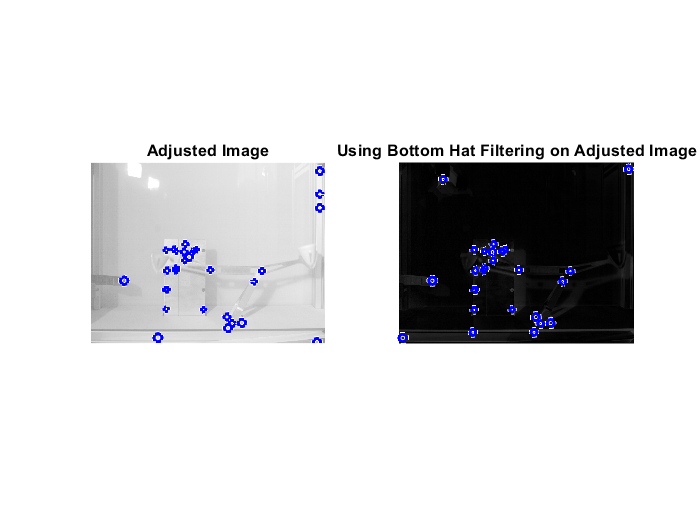

clear
%chunk0 = load('Ballenwerper_sync_380fps_006.npychunk_0.mat');
%chunk1 = load('Ballenwerper_sync_380fps_006.npychunk_0 (1).mat');
chunk2 = load('Ballenwerper_sync_380fps_006.npychunk_2.mat');
chunk3 = load('Ballenwerper_sync_380fps_006.npychunk_3.mat');
chunk4 = load('Ballenwerper_sync_380fps_006.npychunk_4.mat');
chunk5 = load('Ballenwerper_sync_380fps_006.npychunk_5.mat');
chunk6 = load('Ballenwerper_sync_380fps_006.npychunk_6.mat');
chunk7 = load('Ballenwerper_sync_380fps_006.npychunk_7.mat');
chunk8 = load('Ballenwerper_sync_380fps_006.npychunk_8.mat');
chunk9 = load('Ballenwerper_sync_380fps_006.npychunk_9.mat');
 
%videoD1 = cat(1, chunk0.video_data, chunk1.video_data, chunk2.video_data, chunk3.video_data , chunk4.video_data);
videoD2 = cat(1,chunk6.video_data, chunk7.video_data, chunk8.video_data);
videoD3 = cat(1,chunk7.video_data);

%select video
video = videoD3 ; 

% Total number of frames
numFrames = length(video(:,1,1)); 


for f = 1 : 15

    frame = video(f,:,:);
    frame = squeeze(frame);

    % image 1
    subplot(1,2,1)

    AdjustedIm = imadjust(frame,[0 1],[0 1], 0.18);
    imshow(AdjustedIm)
    
    [centers, radii, ~] = imfindcircles(AdjustedIm,[21 50], 'ObjectPolarity','dark'  , 'EdgeThreshold',0.13 , 'Method', 'TwoStage', 'Sensitivity',0.92 );
    viscircles(centers, radii,'EdgeColor','b');

    title("Adjusted Image")

    % image 2
    subplot(1,2,2)
    
    se = strel('disk',100);
    botIm = imbothat(AdjustedIm,se);
    imshow(botIm)
    
    [centers, radii, ~] = imfindcircles(botIm,[21 50] , 'EdgeThreshold',0.13 , 'Method', 'TwoStage', 'Sensitivity',0.92 );
    viscircles(centers, radii,'EdgeColor','b');

    title("Using Bottom Hat Filtering on Adjusted Image")


    drawnow
end